# Finding Distance in a Cartesian Coordinate System

In order to find the distance between two points in the Carteasian plane, we can do this several ways. The firs is to use the distance formula, given in many text books.


$$\sqrt{{\left(x_2 -x_1 \right)}^2 +{\left(y_2 -y_1 \right)}^2 }$$


this formula is derived from the pythagorean theorem, which itself was named after the dinosaur, the pythagosaurus. No J/K.

some greek guy named pythagoras.

the pythagorean theorem is:


$$a^2 +b^2 =c^2$$


so lets say we wish to dinf the distance between the points (-2,3) and (3,-9). lets plot  those points.

clear all
clc
close all

x1 = -2; y1 = 3;
x2 = 3; y2 = -9;
plot(x1,y1,'r*')
hold on
plot(x2,y2,'r*')
axis([-10 10 -10 10])
grid on

you can look at this as a right triangle problem. what is the vertical leg of the right triangle for these points?

vert = [y2:1:y1];
xvert = zeros(1,length(vert))+x1;
plot(xvert,vert)

what is the length of the line? its 3 - (-9), or 12 

now lets look at the horizontal leg of the triangle.

horiz = [x1:1:x2];
yhoriz = zeros(1,length(horiz))+y2;
plot(horiz,yhoriz)

what is the length of the line? its 3 - (-2), or 5 

now we can apply the pythagorean theorem.


$$\sqrt{c^2 }=\sqrt{169}$$



$$c=13$$


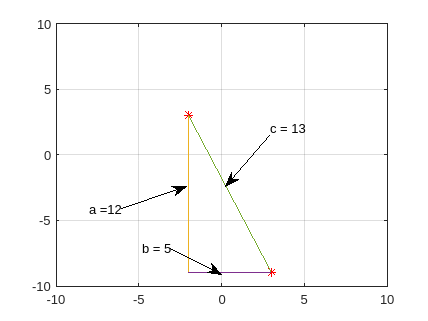

x = [x1 x2];
y = [y1 y2];
plot(x,y)

annotation("textarrow", [0.6302 0.528], [0.5769 0.4188], "String", "c = 13")
annotation("textarrow", [0.399 0.5182], [0.2263 0.1461], "String", "b = 5")
annotation("textarrow", [0.2847 0.4355], [0.3496 0.4188], "String", "a =12")

so notice what we just did. we took the diffrance between x- coordinates and squared it.we took the diffrance between y- coordinates and squared it we added those numbers and then took the square root. in other words;


$$\mathrm{distance}=\sqrt{{\left(x_2 -x_1 \right)}^2 +{\left(y_2 -y_1 \right)}^2 }$$
